# F-16A Level 3 Sizing Analysis — Class-Based Example

This live script performs a Fidelity Level 3 sizing pass for the F-16A example using the toolkit classes supplied with the project. This version captures the W_TO value returned by SizingClassLevel3.size_aircraft().

Main objects used: * AircraftDesign * GeometryLevel3 * AeroLevel3 * PropulsionLevel3 * WeightLevel3 * MissionAnalysisLevel3 * ConstraintAnalysisClass * Requirements * SizingClassLevel3 * SubsystemsLevel3 optional fuel-volume check * SandCLevel3 optional static-stability check

The script assumes the corresponding class files, import utilities, design workbook, requirements table, constraints table, mission profile, and Stability&Control sheet are on the MATLAB path.

clear; close all;

## Project setup

Set this to the folder containing your classes, import utilities, design spreadsheet/workbook, requirements file, constraints file, mission data, and Stability&Control data.

projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";

## Create the aircraft design object

AircraftDesign is the project-level object. It imports the design geometry, fuselage data, propulsion data, weight data, general aircraft data, and requirements reference.

design = AircraftDesign( ...
    designName, ...
    RequirementsName = requirementsName, ...
    ConstraintsName  = constraintsName, ...
    AutoLoad         = true);


disp("AircraftDesign object created:")

AircraftDesign object created:


disp(design)

  AircraftDesign with properties:

                     Name: "F-16A Block 50"
                     geom: [1×1 struct]
                  general: [1×1 struct]
               propulsion: [1×1 struct]
          propulsion_type: "low bpr turbofan"
                  weights: [1×1 struct]
                     type: "Jet fighter"
             requirements: [1×1 struct]
    requirements_filename: []
     constraints_filename: "Constraints"
            WeightResults: []
              AeroResults: []
        PropulsionResults: []
           internalvolume: []


## Build the Level 3 analysis objects

Level 3 uses textbook/component methods. GeometryLevel3 loads component geometry and wetted areas, AeroLevel3 performs component drag buildup, PropulsionLevel3 uses dry/wet thrust and TSFC lapse equations, WeightLevel3 performs component/subsystem empty-weight buildup, MissionAnalysisLevel3 evaluates the mission fuel profile, and SizingClassLevel3 closes W_TO.

geometry_obj     = GeometryLevel3(design);
requirements_obj = Requirements(design);
aero_obj         = AeroLevel3(geometry_obj, design);
propulsion_obj   = PropulsionLevel3(requirements_obj, design);
weight_obj       = WeightLevel3(design);
mission_obj      = MissionAnalysisLevel3(missionName);
constraint_obj   = ConstraintAnalysisClass(design);

sizing_obj       = SizingClassLevel3();

% Consider relegating each instantiation to separate blocks
% Include explanatory text; purpose, outputs, design variables
% Recall most aircraft variables are continuous, but can be grouped
% categorically (engines -> category, thrust -> continuous)

% ConstraintAnalysisClass may either populate its properties directly or, if
% it behaves as a value class in your local inheritance tree, return the values
% through constraint_analysis(). This helper supports both behaviors.
% [constraint_obj, constraintResults] = ensureConstraintResults(constraint_obj);
% 
% disp("Constraint-analysis summary:")
% disp(constraintResults)

## Initialize constraints

We require constraints like "optimum wing-loading" and "minimum T/W" for sizing computations. So we'll initialize them, here.

constraint_obj.constraint_analysis % Requires zero arguments since it pulls from the constraint table.

% constraint_obj.show_constraints %% Optional; remove at leisure

## Run the project sizing class

This calls your SizingClassLevel3 method directly and captures the returned takeoff gross weight. The sizing class still displays its internal iteration table. A persistent trace is reconstructed in the next section for plots and reporting.

W_TO_fromSizingClass = sizing_obj.size_aircraft( ...
    design, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj, ...
    propulsion_obj, ...
    constraint_obj, ...
    requirements_obj, ...
    aero_obj);

     WTO     W_fixed    Fuel_fraction    Empty_weight_fraction    Empty_weight    WTO_new    Difference     Percent_Diff
    _____    _______    _____________    _____________________    ____________    _______    ___________    ____________
    45000     5100         0.23634              0.45656              20545         35679         -9321.5        -20.714 
    35679     5100         0.24208              0.50356              17966         31214           -4464        -12.512 
    31214     5100          0.2466               0.5356              16718         29080         -2134.1         -6.837 
    29080     5100         0.24942              0.55424              16117         28060         -1020.1        -3.5079 
  


fprintf("\nSizingClassLevel3 returned W_TO = %.3f lbf.\n", W_TO_fromSizingClass);


SizingClassLevel3 returned W_TO = 27125.867 lbf.


fprintf("Plot sections below read from the Level 3 object properties populated by the sizing run.\n");

Plot sections below read from the Level 3 object properties populated by the sizing run.


## Optional subsystem fuel-volume check

SubsystemsLevel3 estimates internal volume and fuel volume using the current geometry and the final fuel weight. This is a diagnostic check; it is not part of the sizing convergence loop above.

subsystemSummary = table();
if exist('SubsystemsLevel3', 'class') == 8 || exist('SubsystemsLevel3.m', 'file') == 2
    try
        % Use the fuel burn already stored on weight_obj by MissionAnalysisLevel3.
        subsystems_obj = SubsystemsLevel3(geometry_obj, weight_obj, design);
        fuelVolumeOK = subsystems_obj.checkfuelvol(subsystems_obj.internal_volume, subsystems_obj.fuel_volume);

        subsystemSummary = table( ...
            subsystems_obj.internal_volume, ...
            subsystems_obj.fuel_volume, ...
            fuelVolumeOK, ...
            'VariableNames', {'InternalVolume_gal', 'FuelVolumeRequired_gal', 'IsFuelVolumeSufficient'});

        disp("Optional Level 3 subsystem/fuel-volume summary:")
        disp(subsystemSummary)
    catch ME
        warning("SubsystemsLevel3 check was skipped: %s", ME.message);
    end
end

Optional Level 3 subsystem/fuel-volume summary:


    InternalVolume_gal    FuelVolumeRequired_gal    IsFuelVolumeSufficient
    __________________    ______________________    ______________________
          11226                   998.74                    true          


## Optional longitudinal static-stability check

SandCLevel3 needs component weights and x-locations. This script attempts to extract those from the Stability&Control data loaded by SandCUtils. If the layout cannot be inferred, it skips the static-stability call and tells you where to enter the vectors manually.

stabilitySummary = table();
if exist('SandCLevel3', 'class') == 8 || exist('SandCLevel3.m', 'file') == 2
    try
        sandc_obj = SandCLevel3(design);
        [component_weight_list, component_weight_x_locations, stabilityInputTable] = ...
            tryBuildSandCInputs(sandc_obj.weightlocations);

        if isempty(component_weight_list) || isempty(component_weight_x_locations)
            warning("%s", ...
                "Could not automatically infer component weight and x-location vectors from sandc_obj.weightlocations. " + ...
                "Edit component_weight_list and component_weight_x_locations manually in this section to run the static-stability check.");
        else
            disp("Static-stability component inputs inferred from sandc_obj.weightlocations:")
            disp(stabilityInputTable)

            cruiseState = [ ...
                mission_obj.missiondata.Cruise.MachNumber, ...
                mission_obj.missiondata.Cruise.Altitudeft, ...
                0, ...
                weight_obj.W_TO];

            i_w = 0;
            epsilon = 0;

            [SM, StabilityResults] = sandc_obj.get_static_margin( ...
                geometry_obj, ...
                aero_obj, ...
                design, ...
                cruiseState, ...
                component_weight_list, ...
                component_weight_x_locations, ...
                i_w, ...
                epsilon);

            stabilitySummary = struct2tableForDisplay(StabilityResults);
            disp("Optional Level 3 static-stability summary:")
            disp(stabilitySummary)
        end
    catch ME
        warning("SandCLevel3 static-stability check was skipped: %s", ME.message);
    end
end

Static-stability component inputs inferred from sandc_obj.weightlocations:


      Component       Weight_lbf    XLocation_ft
    ______________    __________    ____________
    "Wing"               1785          27.28    
    "Fuselage"           3652             26    
    "HT"                  648             41    
    "VT"                  360             40    
    "Nacelles"            186             29    
    "Strakes"              90             17    
    "Engine"             4730             33    
    "Gear"               1066             26    
    "InletDuct"           728             22    
    "Controls"            472             27    
    "Electrical"          533             33    
    "Hydraulics"          367             33    
    "ECS"                 360             27    
    "Other"              2016             20    
    "Avionics"           2541             15    
    "Armaments"           440             26    
    "FixedPayloa

Optional Level 3 static-stability summary:


              Metric                                              Value                               
    ___________________________    ___________________________________________________________________
    "IsStaticStable"               "false"                                                            
    "IsNeutral"                    "false"                                                            
    "IsUnstable"                   "true"                                                             
    "Assessment"                   "Unstable"                                                         
    "Reason"                       "Static margin is negative, so the CG is aft of the neutral point."
    "SM"                           "-0.014672"                                                        
    "Cm_alpha"                     "72.1975"                                                          
    "

## Plot gross-weight convergence

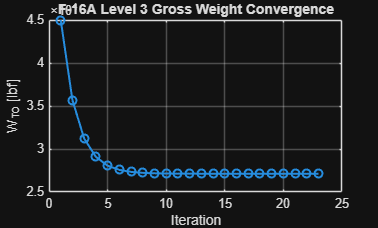

figure('Name', 'Level 3 Gross Weight Convergence');
iterationIdx = 1:height(sizing_obj.results_table);
plot(iterationIdx, sizing_obj.results_table.WTO, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 3 Gross Weight Convergence');

% Source: sizing_obj.results_table populated by SizingClassLevel3.

## Plot closure error

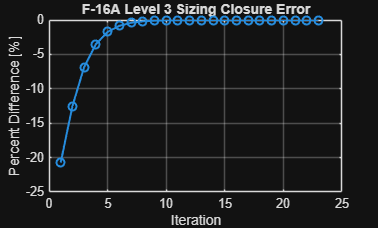

figure('Name', 'Level 3 Closure Error');
iterationIdx = 1:height(sizing_obj.results_table);
plot(iterationIdx, sizing_obj.results_table.Percent_Diff, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 3 Sizing Closure Error');

% Source: sizing_obj.results_table populated by SizingClassLevel3.

## Plot final weight breakdown

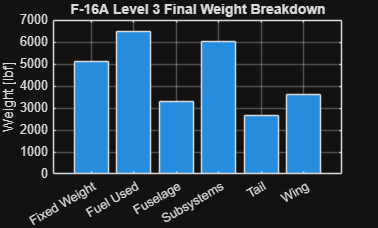

weightBreakdownComponents = categorical([ ...
    "Wing"; ...
    "Tail"; ...
    "Fuselage"; ...
    "Subsystems"; ...
    "Fuel Used"; ...
    "Fixed Weight"]);

% Pull directly from the WeightLevel3 object populated by the sizing pass.
% weight_obj.subsystems is a struct, so use its scalar .total field.
weightBreakdown_lbf = [ ...
    weight_obj.wings; ...
    weight_obj.tail; ...
    weight_obj.fuselage; ...
    weight_obj.subsystems.total; ...
    weight_obj.total_fuel_used; ...
    weight_obj.W_fixed];

figure('Name', 'Level 3 Final Weight Breakdown');
bar(weightBreakdownComponents, weightBreakdown_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 3 Final Weight Breakdown');

% Source: weight_obj.wings, weight_obj.tail, weight_obj.fuselage,
% weight_obj.subsystems.total, weight_obj.total_fuel_used, weight_obj.W_fixed.

## Plot final mission fuel by segment

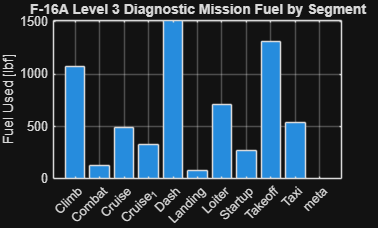

missionSegmentNames = string(fieldnames(mission_obj.missiondata));
missionFuel_lbf = mission_obj.mission_fuel(:);

% MissionAnalysisLevel3 stores one fuel-burn entry per missiondata field.
% Trim defensively in case a profile has an extra metadata field.
nMissionRows = min(numel(missionSegmentNames), numel(missionFuel_lbf));
missionSegmentNames = missionSegmentNames(1:nMissionRows);
missionFuel_lbf = missionFuel_lbf(1:nMissionRows);

figure('Name', 'Level 3 Mission Fuel by Segment');
bar(categorical(missionSegmentNames), missionFuel_lbf);
grid on;
ylabel('Fuel Used [lbf]');
title('F-16A Level 3 Diagnostic Mission Fuel by Segment');

% Source: mission_obj.mission_fuel populated by MissionAnalysisLevel3.

## Plot Level 3 aerodynamic snapshot

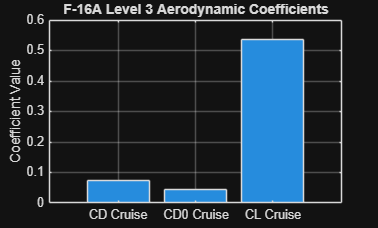

% Refresh the cruise aerodynamic state using the existing AeroLevel3 object.
cruiseState = [ ...
    mission_obj.missiondata.Cruise.MachNumber, ...
    mission_obj.missiondata.Cruise.Altitudeft, ...
    0, ...
    weight_obj.W_TO];

airfoiltype = geometry_obj.mainwings.airfoil_type;
if isempty(airfoiltype)
    airfoiltype = "cambered";
end

aero_obj.DragResults = aero_obj.get_design_drag( ...
    geometry_obj, ...
    design, ...
    propulsion_obj, ...
    weight_obj.W_TO, ...
    cruiseState, ...
    airfoiltype);

aero_obj.CD0 = aero_obj.DragResults.CD0_design;
aero_obj.CD  = aero_obj.DragResults.CD_design;
aero_obj.D   = aero_obj.DragResults.D_design;

figure('Name', 'Level 3 Aerodynamic Coefficients');
aeroCoefficientNames = categorical(["CD0 Cruise"; "CD Cruise"; "CL Cruise"]);
aeroCoefficientValues = [aero_obj.CD0; aero_obj.CD; aero_obj.CL];
bar(aeroCoefficientNames, aeroCoefficientValues);
grid on;
ylabel('Coefficient Value');
title('F-16A Level 3 Aerodynamic Coefficients');

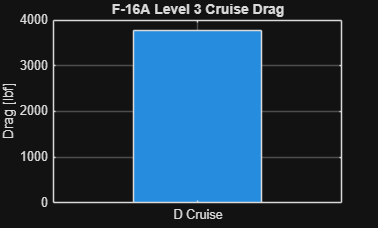


figure('Name', 'Level 3 Cruise Drag');
bar(categorical("D Cruise"), aero_obj.D);
grid on;
ylabel('Drag [lbf]');
title('F-16A Level 3 Cruise Drag');

% Source: aero_obj.DragResults, aero_obj.CD0, aero_obj.CD, aero_obj.CL, aero_obj.D.

## Save results into the AircraftDesign object

AircraftDesign is a handle class, so these assignments persist on the design object during this MATLAB session.

if ~isstruct(design.WeightResults)
    design.WeightResults = struct();
end
if ~isstruct(design.AeroResults)
    design.AeroResults = struct();
end
if ~isstruct(design.PropulsionResults)
    design.PropulsionResults = struct();
end
if ~isstruct(design.internalvolume)
    design.internalvolume = struct();
end

% Save the object-backed Level 3 results without depending on finalState or
% reconstructed summary tables.
design.WeightResults.Level3SizingTable = sizing_obj.results_table;
design.WeightResults.Level3MissionFuel = mission_obj.mission_fuel;
design.WeightResults.W_TO_fromSizingClass = W_TO_fromSizingClass;
design.WeightResults.W_TO              = weight_obj.W_TO;
design.WeightResults.OEW               = weight_obj.OEW.total;
design.WeightResults.FuelUsed          = weight_obj.total_fuel_used;
design.WeightResults.FixedWeight       = weight_obj.W_fixed;
design.WeightResults.WingWeight        = weight_obj.wings;
design.WeightResults.TailWeight        = weight_obj.tail;
design.WeightResults.FuselageWeight    = weight_obj.fuselage;
design.WeightResults.SubsystemWeight   = weight_obj.subsystems.total;

design.AeroResults.Level3.CD0_cruise   = aero_obj.CD0;
design.AeroResults.Level3.CD_cruise    = aero_obj.CD;
design.AeroResults.Level3.CL_cruise    = aero_obj.CL;
design.AeroResults.Level3.D_cruise_lbf = aero_obj.D;
design.AeroResults.Level3.S_wet        = geometry_obj.design.S_wet;

design.PropulsionResults.Level3.T0     = propulsion_obj.T0;

if isstruct(propulsion_obj.TSFC)
    design.PropulsionResults.Level3.TSFC = propulsion_obj.TSFC;
end

if ~isempty(subsystemSummary)
    design.internalvolume.Level3 = subsystemSummary;
end

if ~isempty(stabilitySummary)
    design.AeroResults.Level3.StaticStability = stabilitySummary;
end

fprintf("\nSaved object-backed Level 3 sizing results into design.WeightResults, design.AeroResults, design.PropulsionResults, and optional diagnostic fields.\n");


Saved object-backed Level 3 sizing results into design.WeightResults, design.AeroResults, design.PropulsionResults, and optional diagnostic fields.


## Local helper functions

function assertClassOrFileExists(className)
    className = string(className);
    existsAsClass = exist(char(className), 'class') == 8;
    existsAsFile  = exist(char(className + ".m"), 'file') == 2;

    if ~(existsAsClass || existsAsFile)
        error("Required class/file '%s' was not found on the MATLAB path. Check projectRoot/addpath.", className);
    end
end

function [constraint_obj, constraintResults] = ensureConstraintResults(constraint_obj)
    needsRun = isempty(constraint_obj.optimal_WS) || isempty(constraint_obj.min_TW);

    if needsRun
        [TW_table, T_Wto_takeoff, optimal_WS, min_TW, Landing, Wto_S_landing, T0_W0, W0_S_ref, T_Wto_required] = ...
            constraint_obj.constraint_analysis();

        constraint_obj.TW_table        = TW_table;
        constraint_obj.T_Wto_takeoff   = T_Wto_takeoff;
        constraint_obj.optimal_WS      = optimal_WS;
        constraint_obj.min_TW          = min_TW;
        constraint_obj.Landing         = Landing;
        constraint_obj.Wto_S_landing   = Wto_S_landing;
        constraint_obj.T0_W0           = T0_W0;
        constraint_obj.W0_S_ref        = W0_S_ref;
        constraint_obj.T_Wto_required  = T_Wto_required;
    end

    constraintResults = table( ...
        constraint_obj.optimal_WS, ...
        constraint_obj.min_TW, ...
        constraint_obj.Wto_S_landing, ...
        'VariableNames', {'OptimalWingLoading_psf', 'MinimumThrustLoading', 'LandingWingLoadingLimit_psf'});
end

function missionSummary = summarizeMissionData(missiondata)
    segmentNames = fieldnames(missiondata);
    rows = strings(0, 1);
    mach = nan(0, 1);
    altitude = nan(0, 1);
    range = nan(0, 1);
    time = nan(0, 1);
    payloadDrop = nan(0, 1);
    cd0 = nan(0, 1);
    e = nan(0, 1);
    tsfc = nan(0, 1);

    for i = 1:numel(segmentNames)
        name = segmentNames{i};
        segment = missiondata.(name);

        rows(end+1, 1) = string(name);
        mach(end+1, 1) = getFieldOrNaN(segment, 'MachNumber');
        altitude(end+1, 1) = getFieldOrNaN(segment, 'Altitudeft');
        range(end+1, 1) = getFieldOrNaN(segment, 'Rangeft');
        time(end+1, 1) = getFieldOrNaN(segment, 'Timemin');
        payloadDrop(end+1, 1) = getFieldOrNaN(segment, 'PayloadDroplbf');
        cd0(end+1, 1) = getFieldOrNaN(segment, 'CD0');
        e(end+1, 1) = getFieldOrNaN(segment, 'e');
        tsfc(end+1, 1) = getFieldOrNaN(segment, 'TSFC');
    end

    missionSummary = table(rows, mach, altitude, range, time, payloadDrop, cd0, e, tsfc, ...
        'VariableNames', {'Segment', 'MachNumber', 'Altitude_ft', 'Range_ft', 'Time_min', 'PayloadDrop_lbf', 'CD0', 'e', 'TSFC'});
end

function value = getFieldOrNaN(s, fieldName)
    if isstruct(s) && isfield(s, fieldName)
        value = s.(fieldName);
    elseif istable(s) && any(strcmp(s.Properties.VariableNames, fieldName))
        value = s.(fieldName);
    else
        value = NaN;
    end

    if ~isscalar(value) || ~isnumeric(value)
        value = NaN;
    end
end

function [results_table, finalState, segmentTable] = runLevel3SizingTrace(design, geometry_obj, mission_obj, weight_obj, propulsion_obj, constraint_obj, requirements_obj, aero_obj)
    W_S = constraint_obj.optimal_WS;
    T_W = constraint_obj.min_TW;

    assert(~isempty(W_S) && isfinite(W_S), 'constraint_obj.optimal_WS must be finite.');
    assert(~isempty(T_W) && isfinite(T_W), 'constraint_obj.min_TW must be finite.');

    W_TO = weight_obj.W_TO_guess;
    W_fixed = mission_obj.missiondata.Startup.PayloadFixedlbf;

    tol = 1e-3;
    maxIteration = 40;
    rows = [];
    lastSegmentTable = table();
    lastOEW = struct();
    lastAero = struct();

    for iteration = 1:maxIteration
        geometry_obj.mainwings.S_ref = W_TO / W_S;
        geometry_obj.design.S_wet = geometry_obj.get_design_S_wet(W_TO);

        % This mirrors the current assignment in SizingClassLevel3. If you
        % later correct the tail return order in the class, update this trace
        % to match that corrected class behavior.
        [geometry_obj.HT.S_ref, geometry_obj.VT.S_ref] = geometry_obj.size_tail(design, geometry_obj.mainwings.S_ref);

        propulsion_obj.T0 = T_W * W_TO;

        weight_obj.W_TO = W_TO;
        weight_obj.W_fixed = W_fixed;

        [fuel_used, fuel_fraction] = mission_obj.get_mission_fuel( ...
            constraint_obj, ...
            design, ...
            geometry_obj, ...
            propulsion_obj, ...
            weight_obj, aero_obj);

        OEW = weight_obj.get_OEW( ...
            propulsion_obj, ...
            design, ...
            geometry_obj, ...
            weight_obj.W_TO, ...
            requirements_obj);

        OEW_frac = OEW.total / W_TO;

        W_TO_new = fuel_used + W_fixed + OEW.total;
        difference = W_TO_new - W_TO;
        percentDifference = 100 * difference / W_TO;

        aeroSnapshot = computeLevel3AeroSnapshot( ...
            aero_obj, ...
            geometry_obj, ...
            design, ...
            propulsion_obj, ...
            mission_obj, ...
            W_TO);

        TSFCSnapshot = computeLevel3TSFCSnapshot(propulsion_obj, design, mission_obj, W_TO);

        lastSegmentTable = estimateLevel3MissionSegments( ...
            mission_obj, ...
            propulsion_obj, ...
            design, ...
            W_TO, ...
            W_S, ...
            geometry_obj.mainwings.S_ref, ...
            geometry_obj.mainwings.AR);

        rows(end+1, :) = [ ...
            iteration, ...
            W_TO, ...
            W_fixed, ...
            fuel_used, ...
            fuel_fraction, ...
            OEW_frac, ...
            OEW.total, ...
            getStructFieldOrNaN(OEW, 'W_Wing'), ...
            getStructFieldOrNaN(OEW, 'W_tail'), ...
            getStructFieldOrNaN(OEW, 'W_fuselage'), ...
            getNestedStructFieldOrNaN(OEW, {'W_subsystems', 'total'}), ...
            getNestedStructFieldOrNaN(weight_obj, {'engine', 'installed'}), ...
            geometry_obj.mainwings.S_ref, ...
            geometry_obj.design.S_wet, ...
            geometry_obj.HT.S_ref, ...
            geometry_obj.VT.S_ref, ...
            propulsion_obj.T0, ...
            aeroSnapshot.CD0, ...
            aeroSnapshot.CD, ...
            aeroSnapshot.CL, ...
            aeroSnapshot.D, ...
            TSFCSnapshot.Cruise * 3600, ...
            TSFCSnapshot.Dash * 3600, ...
            TSFCSnapshot.Loiter * 3600, ...
            W_TO_new, ...
            difference, ...
            percentDifference]; %#ok<AGROW>

        lastOEW = OEW;
        lastAero = aeroSnapshot;

        if abs(difference) < tol
            W_TO = W_TO_new;
            break;
        end

        W_TO = W_TO_new;
    end

    results_table = array2table(rows, 'VariableNames', { ...
        'Iteration', ...
        'WTO_lbf', ...
        'FixedWeight_lbf', ...
        'FuelUsed_lbf', ...
        'FuelFraction', ...
        'EmptyWeightFraction', ...
        'OEW_total_lbf', ...
        'WingWeight_lbf', ...
        'TailWeight_lbf', ...
        'FuselageWeight_lbf', ...
        'SubsystemWeight_lbf', ...
        'InstalledEngineWeight_lbf', ...
        'WingReferenceArea_ft2', ...
        'WettedArea_ft2', ...
        'HorizontalTailArea_ft2', ...
        'VerticalTailArea_ft2', ...
        'SeaLevelStaticThrust_lbf', ...
        'CruiseCD0', ...
        'CruiseCD', ...
        'CruiseCL', ...
        'CruiseDrag_lbf', ...
        'CruiseTSFC_per_hr', ...
        'DashTSFC_per_hr', ...
        'LoiterTSFC_per_hr', ...
        'WTO_new_lbf', ...
        'Difference_lbf', ...
        'PercentDifference'});

    last = results_table(end, :);

    finalState = struct();
    finalState.W_TO_lbf = last.WTO_new_lbf;
    finalState.OEW_total_lbf = last.OEW_total_lbf;
    finalState.W_wing_lbf = last.WingWeight_lbf;
    finalState.W_tail_lbf = last.TailWeight_lbf;
    finalState.W_fuselage_lbf = last.FuselageWeight_lbf;
    finalState.W_subsystems_lbf = last.SubsystemWeight_lbf;
    finalState.W_engine_installed_lbf = last.InstalledEngineWeight_lbf;
    finalState.W_fixed_lbf = last.FixedWeight_lbf;
    finalState.W_fuel_lbf = last.FuelUsed_lbf;
    finalState.fuel_fraction = last.FuelFraction;
    finalState.empty_weight_fraction = last.EmptyWeightFraction;
    finalState.S_ref_ft2 = last.WingReferenceArea_ft2;
    finalState.S_wet_ft2 = last.WettedArea_ft2;
    finalState.S_HT_ft2 = last.HorizontalTailArea_ft2;
    finalState.S_VT_ft2 = last.VerticalTailArea_ft2;
    finalState.T0_lbf = last.SeaLevelStaticThrust_lbf;
    finalState.CD0_cruise = last.CruiseCD0;
    finalState.CD_cruise = last.CruiseCD;
    finalState.CL_cruise = last.CruiseCL;
    finalState.D_cruise_lbf = last.CruiseDrag_lbf;
    finalState.TSFC_cruise_per_hr = last.CruiseTSFC_per_hr;
    finalState.TSFC_dash_per_hr = last.DashTSFC_per_hr;
    finalState.TSFC_loiter_per_hr = last.LoiterTSFC_per_hr;
    finalState.OEW_struct = lastOEW;
    finalState.Aero_struct = lastAero;

    segmentTable = lastSegmentTable;
end

function aeroSnapshot = computeLevel3AeroSnapshot(aero_obj, geometry_obj, design, propulsion_obj, mission_obj, W_TO)
    cruise = mission_obj.missiondata.Cruise;
    alpha_deg = 0;
    state = [cruise.MachNumber, cruise.Altitudeft, alpha_deg, W_TO];
    airfoiltype = getAirfoilTypeOrDefault(geometry_obj, "cambered");

    aeroSnapshot = struct('CD0', NaN, 'CD', NaN, 'CL', NaN, 'D', NaN, 'DragResults', []);

    try
        DragResults = aero_obj.get_design_drag( ...
            geometry_obj, ...
            design, ...
            propulsion_obj, ...
            W_TO, ...
            state, ...
            airfoiltype);

        aeroSnapshot.CD0 = getStructFieldOrNaN(DragResults, 'CD0_design');
        aeroSnapshot.CD = getStructFieldOrNaN(DragResults, 'CD_design');
        aeroSnapshot.CL = aero_obj.CL;
        aeroSnapshot.D = getStructFieldOrNaN(DragResults, 'D_design');
        aeroSnapshot.DragResults = DragResults;
    catch ME
        warning("Level 3 aerodynamic cruise snapshot failed: %s", ME.message);
    end
end

function airfoiltype = getAirfoilTypeOrDefault(geometry_obj, defaultValue)
    airfoiltype = defaultValue;
    try
        if isfield(geometry_obj.mainwings, 'airfoil_type') && strlength(string(geometry_obj.mainwings.airfoil_type)) > 0
            airfoiltype = string(geometry_obj.mainwings.airfoil_type);
        end
    catch
        airfoiltype = defaultValue;
    end
end

function TSFCSnapshot = computeLevel3TSFCSnapshot(propulsion_obj, design, mission_obj, W_TO)
    cruise = mission_obj.missiondata.Cruise;
    dash = mission_obj.missiondata.Dash;
    loiter = mission_obj.missiondata.Loiter;

    TSFCSnapshot = struct();
    TSFCSnapshot.Cruise = getLevel3TSFC(propulsion_obj, design, cruise, "dry");
    TSFCSnapshot.Dash = getLevel3TSFC(propulsion_obj, design, dash, "wet");
    TSFCSnapshot.Loiter = getLevel3TSFC(propulsion_obj, design, loiter, "dry");
end

function TSFC = getLevel3TSFC(propulsion_obj, design, segment, dryWet)
    if dryWet == "dry"
        TSFC = propulsion_obj.get_TSFC( ...
            [segment.MachNumber, segment.Altitudeft], ...
            "dry", ...
            design.propulsion.ThrustseaLevellbf.Dry, ...
            design.propulsion.TSFCseaLevelperHour.Dry, ...
            design.propulsion.E.Dry, ...
            design.propulsion.F1.Dry, ...
            design.propulsion.F2.Dry, ...
            1.0);
    else
        TSFC = propulsion_obj.get_TSFC( ...
            [segment.MachNumber, segment.Altitudeft], ...
            "wet", ...
            design.propulsion.ThrustseaLevellbf.Wet, ...
            design.propulsion.TSFCseaLevelperHour.Wet, ...
            design.propulsion.E.Wet, ...
            design.propulsion.F1.Wet, ...
            design.propulsion.F2.Wet, ...
            1.0);
    end
end

function segmentTable = estimateLevel3MissionSegments(mission_obj, propulsion_obj, design, W_TO, W_S, S_ref, AR)
    m = mission_obj.missiondata;

    segment = strings(0, 1);
    W_in = nan(0, 1);
    W_out = nan(0, 1);
    fuel = nan(0, 1);

    W_current = W_TO;

    [W_next, f] = constantWeightFractionSegment(W_current, 0.99);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Startup", W_current, W_next, f);
    W_current = W_next;

    [W_next, f] = constantWeightFractionSegment(W_current, 0.98);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Taxi", W_current, W_next, f);
    W_current = W_next;

    [W_next, f] = constantWeightFractionSegment(W_current, 0.95);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Takeoff", W_current, W_next, f);
    W_current = W_next;

    [W_next, f] = climbSegmentSimple(W_current, m.Climb.MachNumber);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Climb", W_current, W_next, f);
    W_current = W_next;

    TSFC_cruise = getLevel3TSFC(propulsion_obj, design, m.Cruise, "dry");
    [W_next, f] = breguetRangeSegment(W_current, TSFC_cruise, m.Cruise.Rangeft, m.Cruise.MachNumber*m.Cruise.afts, m.Cruise.qlbfft2, m.Cruise.CD0, m.Cruise.e, AR, S_ref);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Cruise", W_current, W_next, f);
    W_current = W_next;

    TSFC_dash = getLevel3TSFC(propulsion_obj, design, m.Dash, "wet");
    [W_next, f] = breguetRangeSegment(W_current, TSFC_dash, m.Dash.Rangeft, m.Dash.MachNumber*m.Dash.afts, m.Dash.qlbfft2, m.Dash.CD0, m.Dash.e, AR, S_ref);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Dash", W_current, W_next, f);
    W_current = W_next;

    TSFC_combat = getLevel3TSFC(propulsion_obj, design, m.Combat, "wet");
    [W_next, f] = enduranceSegment(W_current, TSFC_combat, m.Combat.Timemin, m.Combat.qlbfft2, m.Combat.CD0, m.Combat.e, AR, S_ref, m.Combat.PayloadDroplbf);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Combat", W_current, W_next, f);
    W_current = W_next;

    TSFC_cruise2 = getLevel3TSFC(propulsion_obj, design, m.Cruise_1, "dry");
    [W_next, f] = breguetRangeSegment(W_current, TSFC_cruise2, m.Cruise_1.Rangeft, m.Cruise_1.MachNumber*m.Cruise_1.afts, m.Cruise_1.qlbfft2, m.Cruise_1.CD0, m.Cruise_1.e, AR, S_ref);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Cruise_1", W_current, W_next, f);
    W_current = W_next;

    TSFC_loiter = getLevel3TSFC(propulsion_obj, design, m.Loiter, "dry");
    [W_next, f] = enduranceSegment(W_current, TSFC_loiter, m.Loiter.Timemin, m.Loiter.qlbfft2, m.Loiter.CD0, m.Loiter.e, AR, S_ref, 0);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Loiter", W_current, W_next, f);
    W_current = W_next;

    [W_next, f] = constantWeightFractionSegment(W_current, 0.995);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Landing", W_current, W_next, f);

    segmentTable = table(segment, W_in, W_out, fuel, 'VariableNames', {'Segment', 'W_in_lbf', 'W_out_lbf', 'FuelUsed_lbf'});
end

function LD = computeLDLevel3(W, q, S_ref, CD0, e, AR)
    CL = 2 * W / (q * S_ref);
    K = 1 / (pi * e * AR);
    CD = CD0 + K * CL^2;
    LD = CL / CD;
end

function [W_out, fuel_used] = breguetRangeSegment(W_in, TSFC, distance_ft, V_fts, q, CD0, e, AR, S_ref)
    LD = computeLDLevel3(W_in, q, S_ref, CD0, e, AR);
    WF = exp(-((distance_ft * TSFC) / (V_fts * LD)));
    fuel_used = W_in * (1 - WF);
    W_out = W_in - fuel_used;
end

function [W_out, fuel_used] = enduranceSegment(W_in, TSFC, time_min, q, CD0, e, AR, S_ref, payloadDrop_lbf)
    LD = computeLDLevel3(W_in, q, S_ref, CD0, e, AR);
    WF = exp(-(time_min * 60 * TSFC / LD));
    fuel_used = W_in * (1 - WF);
    W_out = W_in - fuel_used - payloadDrop_lbf;
end

function [W_out, fuel_used] = climbSegmentSimple(W_in, Mach)
    WF = 1.0065 - 0.0325 * Mach;
    fuel_used = (1 - WF) * W_in;
    W_out = W_in - fuel_used;
end

function [W_out, fuel_used] = constantWeightFractionSegment(W_in, WF)
    W_out = W_in * WF;
    fuel_used = W_in - W_out;
end

function [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, name, win, wout, f)
    segment(end+1, 1) = string(name);
    W_in(end+1, 1) = win;
    W_out(end+1, 1) = wout;
    fuel(end+1, 1) = f;
end

function value = getStructFieldOrNaN(s, fieldName)
    if isstruct(s) && isfield(s, fieldName)
        value = s.(fieldName);
    else
        value = NaN;
    end

    if ~isscalar(value) || ~isnumeric(value)
        value = NaN;
    end
end

function value = getNestedStructFieldOrNaN(s, fieldPath)
    value = NaN;
    try
        current = s;
        for i = 1:numel(fieldPath)
            key = fieldPath{i};
            if isstruct(current) && isfield(current, key)
                current = current.(key);
            elseif isobject(current) && isprop(current, key)
                current = current.(key);
            else
                return;
            end
        end

        if isscalar(current) && isnumeric(current)
            value = current;
        end
    catch
        value = NaN;
    end
end

function [weights, xLocations, inputTable] = tryBuildSandCInputs(weightlocations)
    % This function supports common table/struct layouts for Stability&Control
    % sheets. If your exact field names differ, manually set weights and
    % xLocations in the static-stability section above.

    weights = [];
    xLocations = [];
    names = strings(0, 1);

    if istable(weightlocations)
        vars = string(weightlocations.Properties.VariableNames);
        wVar = findFirstContains(vars, ["weight", "w_lbf", "wlbf", "w"]);
        xVar = findFirstContains(vars, ["x", "station", "location"]);
        if strlength(wVar) > 0 && strlength(xVar) > 0
            weights = weightlocations.(wVar);
            xLocations = weightlocations.(xVar);
            if ~isempty(weightlocations.Properties.RowNames)
                names = string(weightlocations.Properties.RowNames(:));
            else
                names = "Component_" + string((1:numel(weights)).');
            end
        end
    elseif isstruct(weightlocations)
        componentNames = fieldnames(weightlocations);
        for i = 1:numel(componentNames)
            compName = componentNames{i};
            comp = weightlocations.(compName);
            if isstruct(comp)
                [w, x] = findWeightAndXInStruct(comp);
                if isfinite(w) && isfinite(x)
                    names(end+1, 1) = string(compName); %#ok<AGROW>
                    weights(end+1, 1) = w; %#ok<AGROW>
                    xLocations(end+1, 1) = x; %#ok<AGROW>
                end
            end
        end
    end

    weights = weights(:);
    xLocations = xLocations(:);
    valid = isfinite(weights) & isfinite(xLocations) & weights > 0;
    weights = weights(valid);
    xLocations = xLocations(valid);
    names = names(valid);

    inputTable = table(names, weights, xLocations, 'VariableNames', {'Component', 'Weight_lbf', 'XLocation_ft'});
end

function name = findFirstContains(vars, patterns)
    name = "";
    lowerVars = lower(vars);
    for p = 1:numel(patterns)
        idx = find(contains(lowerVars, lower(patterns(p))), 1);
        if ~isempty(idx)
            name = vars(idx);
            return;
        end
    end
end

function [w, x] = findWeightAndXInStruct(s)
    w = NaN;
    x = NaN;
    f = fieldnames(s);
    lf = lower(string(f));

    wIdx = find(contains(lf, "weight") | contains(lf, "w_lbf") | contains(lf, "wlbf") | lf == "w", 1);
    xIdx = find(contains(lf, "x") | contains(lf, "station") | contains(lf, "location"), 1);

    if ~isempty(wIdx)
        candidate = s.(f{wIdx});
        if isnumeric(candidate) && isscalar(candidate)
            w = candidate;
        end
    end

    if ~isempty(xIdx)
        candidate = s.(f{xIdx});
        if isnumeric(candidate) && isscalar(candidate)
            x = candidate;
        end
    end
end

function outTable = struct2tableForDisplay(s)
    names = string(fieldnames(s));
    values = strings(numel(names), 1);

    for i = 1:numel(names)
        value = s.(names(i));
        if isnumeric(value) || islogical(value)
            if isscalar(value)
                values(i) = string(value);
            else
                values(i) = "[numeric array]";
            end
        elseif isstring(value) || ischar(value)
            values(i) = string(value);
        else
            values(i) = "[" + string(class(value)) + "]";
        end
    end

    outTable = table(names, values, 'VariableNames', {'Metric', 'Value'});
end